# Plot Fig. S1

addpath(genpath('../../public_code'))
% %%
addpath(genpath('~/MyDocuments/biophysics/projects/social_mice'))
% addpath(genpath('~/MyDocuments/biophysics/projects/maxent/misctools'))
% addpath(genpath('~/MyDocuments/biophysics/projects/maxent/UGM'))


% load sme_6h_male_before_timp_180511.mat mirExp_flat2 cijExp_flat2 ccijExp_flat2
%...
%     jij2_gd hir2_gd ...
    
% this one doesn't have pseudocount


% mirExp_flat2_old = mirExp_flat2;
% cijExp_flat2_old = cijExp_flat2;
% ccijExp_flat2_old = ccijExp_flat2;


nDays = 10;

nstrain = 'male_before_timp_180511'; nNodes = 15;
nEdges = nNodes*(nNodes-1)/2 ;
nStates = 4;

jij2_gd_before = zeros(nEdges, nDays);
hir2_gd_before = zeros((nStates-1)*nNodes, nDays);
dh2_gd_before = zeros(nNodes, nDays);
% 
% mirExp_flat2 = zeros((nStates-1)*nNodes, nDays);
% cijExp_flat2 = zeros(nEdges, nDays);
% ccijExp_flat2 = zeros(nEdges, nDays);

% hir2_gd_before = zeros((nStates-1)*nNodes, nDays);
% mfoodExp_flat2 = zeros(nNodes, nDays);


for iday = 1:nDays
    fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
    load(fpday,'jij_gd_eachday','hir_gd_eachday');
    jij2_gd_before(:, iday) = jij_gd_eachday;
    hir2_gd_before(:, iday) = hir_gd_eachday;
    hirMat = reshape(hir_gd_eachday, nNodes, nStates-1);
    dh_before = -(hirMat(:,1)+hirMat(:,3)-hirMat(:,2))';
    dh2_gd_before(:, iday) = dh_before;



%     load(fpday,'mirExp_eachday','cijExp_eachday','ccijExp_eachday');
%     mirExpMat = reshape(mirExp_eachday, nNodes, nStates-1);
%     mirExpMat = [mirExpMat ones(nNodes,1)-sum(mirExpMat,2)];
%     mfoodExp_eachday = mirExpMat(:,2)+mirExpMat(:,4);
%     mfoodExp_flat2(:,iday) = mfoodExp_eachday;
% 
%     mirExp_flat2(:, iday) = mirExp_eachday;
%     cijExp_flat2(:, iday) = cijExp_eachday;
%     ccijExp_flat2(:, iday) = ccijExp_eachday;
end


%%
hirMat2 = zeros(nNodes, nStates, nDays);
for iday = 1:nDays
    hirMat2(:,1:3,iday) = reshape(hir2_gd_before(:,iday), nNodes, nStates-1);
end

hir2_gd_before = -squeeze(hirMat2(:,1,:)+hirMat2(:,3,:)-hirMat2(:,2,:))';


s2 = [];

mirExp_flat2 = zeros(nNodes * (nStates-1), nDays);
cijExp_flat2 = zeros(nNodes * (nNodes-1) / 2, nDays);
ccijExp_flat2 = zeros(nNodes * (nNodes-1) / 2, nDays);
%
for dayId = 0:nDays-1

    fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];

    load(fn,'s');
    s = s';
    s = int64(s);
    s = remove_tunnel(s);

    s = s(:,1801:1800*7);
%     s3(:, :, dayId+1) = s;
    
    s2 = [s2 s];

    %%
    [edgeStruct, nodeMap, edgeMap] = model1_escp_notunnel(nNodes, nStates);

    suffStat = UGM_MRF_computeSuffStat(s', nodeMap, edgeMap, edgeStruct);

    cijExp_eachday = suffStat((nStates-1)*nNodes+1:end) / nSamples ;
    mirExp_eachday = suffStat(1:(nStates-1)*nNodes) / nSamples ;
    ccijExp_eachday = cm_to_cc2(cijExp_eachday, mirExp_eachday, nNodes, nStates);
%        

end


% jij2_gd_before = jij2_gd;
% hir2_gd_before = hir2_gd;
% % jij2_gd_180511 = jij2_gd;
% % hir2_gd_180511 = hir2_gd;
% 
% % load sme_6h_male_after_timp_180526.mat jij2_gd hir2_gd nNodes nStates
% % jij2_gd_after = jij2_gd;
% % hir2_gd_after = hir2_gd;
% 
% nstrain = 'male_after_timp_180526'; nNodes = 15;
% nEdges = nNodes*(nNodes-1)/2 ;
% 
% jij2_gd_after = zeros(nEdges, nDays);
% hir2_gd_after = zeros((nStates-1)*nNodes, nDays);
% 
% for iday = 1:nDays
%     fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
%     load(fpday,'jij_gd_eachday','hir_gd_eachday');
%     jij2_gd_after(:, iday) = jij_gd_eachday;
%     hir2_gd_after(:, iday) = hir_gd_eachday;
% end


## Fig. S1. A

nDays = 10;
mfoodExp_flat2 = zeros(nNodes, nDays);
for iday = 1:nDays
    mirExp_eachday = mirExp_flat2(:,iday);
    mirExpMat = reshape(mirExp_eachday, nNodes, nStates-1);
    mirExpMat = [mirExpMat ones(nNodes,1)-sum(mirExpMat,2)];
    mfoodExp_eachday = mirExpMat(:,2)+mirExpMat(:,4);
    mfoodExp_flat2(:,iday) = mfoodExp_eachday;
end


figure()
plot(mfoodExp_flat2')
xlim([0.5 10.5])
ylim([0.3 0.8])
yticks(0.3:0.1:0.8)
xticks(2:2:10)
set(gca,'fontsize',12)
xlabel('day')
ylabel('m_{i2}+m_{i4}')

## Fig. S1. B

figure()
plot(ccijExp_flat2')
xlim([0.5 10.5])
ylim([-0.1 0.22])
yticks(-0.1:0.1:0.2)
set(gca,'fontsize',12)
xlabel('day')
ylabel('C_{ij}')

## Fig. S1. C


ciExp_flat2 = zeros(nNodes, nDays);
for iday = 1:nDays
    ciExp_flat2(:,iday) = sum(recoverUpt(ccijExp_flat2(:,iday),nNodes),2);
end

figure()
plot(ciExp_flat2')
xlim([0.5 10.5])
set(gca,'fontsize',12)
xlabel('day')
ylabel('C`_i')
ylim([-0.5,1.2])

## Fig. S1. D

nstrain = 'male_before_timp_180511'; nNodes = 15;
nDays = 10;
activ2 = zeros(nNodes, nDays);


for dayId = 0:nDays-1
    fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];
    load(fn,'s');
    s = s';
    s = int64(s);
    s = remove_tunnel(s);
    s = s(:,1801:1800*7);
    activ2(:,dayId+1) = sum(diff(s,1,2)~=0,2)/(60*6*60);  
end

figure()
plot(activ2')
xlim([0.5 10.5])
set(gca,'fontsize',12)
xlabel('day')
ylabel('activity (s^{-1})')
ylim([0 0.04])

## Fig. S1. E

% nstrain = 'male_before_timp_180511'; nNodes = 15;
% nDays = 10;
% s2 = [];
% for dayId = 0:nDays-1
%     
%     fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];
% 
%     load(fn,'s');
%     s = s';
%     s = int64(s);
% 
%     s = remove_tunnel(s);
%     s = s(:,1801:1800*7);
%     s2 = [s2 s];   
% end

%% Correlation 5 days
cijMat_f5 = zeros(nNodes, nNodes); % first 5 days
for t = 1:10800*5
    cijMat_f5 = cijMat_f5 + (s2(:, t)' == s2(:,t));
end
cijMat_f5 = cijMat_f5 / 10800 / 5;
cijMat_f5 = cijMat_f5 - eye(nNodes);

%%
cijMat_l5 = zeros(nNodes, nNodes); % last 5 days
for t = (1:10800*5)+10800*5
    cijMat_l5 = cijMat_l5 + (s2(:, t)' == s2(:,t));
end
cijMat_l5 = cijMat_l5 / 10800 / 5;
cijMat_l5 = cijMat_l5 - eye(nNodes);

%% Compute magnetization
nStates = 4;
mirMat_f5 = zeros(nNodes, nStates);
for istate = 1:nStates
    mirMat_f5(:,istate) = mean((s2(:,1:10800*5) == istate),2);
end

mirMat_l5 = zeros(nNodes, nStates);
for istate = 1:nStates
    mirMat_l5(:,istate) = mean((s2(:,(1:10800*5)+10800*5) == istate),2);
end

%% run bs half to extract cthres and mthres

maxIter = 2e4;
dsSignal = s2(:, 1:10800*5);

nStates = 4;
[edgeStruct, nodeMap, edgeMap] = ...
    model1_escp_notunnel(nNodes, nStates);

edgeStruct.maxIter = maxIter;
[nNodes, nSamples] = size(dsSignal);
nEdges = max(edgeMap(:))-max(nodeMap(:));

nbs = 50;
cijExp_bsmaster = zeros(0);
mirExp_bsmaster = zeros(0);
ccijExp_bsmaster = zeros(0);
ccijExpSum_bsmaster = zeros(0);

for ibs = 1:nbs
    bsSignal = bootstrapData(dsSignal',1800)';
    nBsSamples = size(bsSignal,2);
    suffStat = UGM_MRF_computeSuffStat(bsSignal',nodeMap,edgeMap,edgeStruct);
    mirExp_bsmaster(ibs,:)=suffStat(1:(nStates-1)*nNodes)/nBsSamples;

    cijExp_bsmaster(ibs,:)=suffStat((nStates-1)*nNodes+1:end)/nBsSamples;
    ccijExp_bsmaster(ibs,:)= cm_to_cc2(cijExp_bsmaster(ibs,:),...
        mirExp_bsmaster(ibs,:),nNodes,nStates);
    ccijExpSum_bsmaster(ibs,:) = ...
        sum(recoverUpt(ccijExp_bsmaster(ibs,:), nNodes));
end

cijExp_f5_bsstd = nanstd(cijExp_bsmaster)/sqrt(nSamples/nBsSamples);
mirExp_f5_bsstd = nanstd(mirExp_bsmaster)/sqrt(nSamples/nBsSamples);
ccijExp_f5_bsstd = nanstd(ccijExp_bsmaster)/sqrt(nSamples/nBsSamples);
ccijExpSum_f5_bsstd = nanstd(ccijExpSum_bsmaster)/sqrt(nSamples/nBsSamples);

%% now do the bsstd for the last 5 days

dsSignal = s2(:, (1:10800*5)+10800*5);

nbs = 50;
cijExp_bsmaster = zeros(0);
mirExp_bsmaster = zeros(0);
ccijExp_bsmaster = zeros(0);
ccijExpSum_bsmaster = zeros(0);

for ibs = 1:nbs
    bsSignal = bootstrapData(dsSignal',1800)';
    nBsSamples = size(bsSignal,2);
    suffStat = UGM_MRF_computeSuffStat(bsSignal',nodeMap,edgeMap,edgeStruct);
    mirExp_bsmaster(ibs,:)=suffStat(1:(nStates-1)*nNodes)/nBsSamples;

    cijExp_bsmaster(ibs,:) = suffStat((nStates-1)*nNodes+1:end)/nBsSamples;
    ccijExp_bsmaster(ibs,:) = cm_to_cc2(cijExp_bsmaster(ibs,:),...
        mirExp_bsmaster(ibs,:),nNodes,nStates);
    ccijExpSum_bsmaster(ibs,:) = ...
        sum(recoverUpt(ccijExp_bsmaster(ibs,:), nNodes));
end
cijExp_l5_bsstd = nanstd(cijExp_bsmaster)/sqrt(nSamples/nBsSamples);
mirExp_l5_bsstd = nanstd(mirExp_bsmaster)/sqrt(nSamples/nBsSamples);
ccijExp_l5_bsstd = nanstd(ccijExp_bsmaster)/sqrt(nSamples/nBsSamples);
ccijExpSum_l5_bsstd = nanstd(ccijExpSum_bsmaster)/sqrt(nSamples/nBsSamples);


%%
figure()
% plot(mirMat_f5(:), mirMat_l5(:),'k.',...
%     'markerSize',10)
errorbar(reshape(mirMat_f5(:,1:nStates-1),1,(nStates-1)*nNodes), ...
    reshape(mirMat_l5(:,1:nStates-1),1,(nStates-1)*nNodes),...
    mirExp_l5_bsstd, mirExp_l5_bsstd, ...
    mirExp_f5_bsstd, mirExp_f5_bsstd, 'k.',...
    'markerSize',10)
hold on
plot([0 0.5],[0 0.5],'-','color',[0 0 0]+0.65)
hold off
axis square
axis([0. 0.5 0. 0.5])
c = corr(mirMat_f5(:), mirMat_l5(:));
l=legend(['corr = ' num2str(c,2)]);
l.Location = 'northwest';
xlabel('m_{ir}, first 5 days')
ylabel('m_{ir}, last 5 days')
set(gca,'fontsize',12)
xticks(0:0.1:0.5)
yticks(0:0.1:0.5)

## Fig S1 F

%% Compute ccij
ccijMat_f5 = cijMat_f5 - mirMat_f5 * mirMat_f5';
ccijMat_l5 = cijMat_l5 - mirMat_l5 * mirMat_l5';
ccijMat_f5 = ccijMat_f5 - diag(diag(ccijMat_f5));
ccijMat_l5 = ccijMat_l5 - diag(diag(ccijMat_l5));

figure()
errorbar(makeUpt(ccijMat_f5)', makeUpt(ccijMat_l5)', ...
    ccijExp_l5_bsstd, ccijExp_l5_bsstd, ...
    ccijExp_f5_bsstd, ccijExp_f5_bsstd, ...
    'k.','MarkerSize',10)
hold on
plot([-0.05 0.1],[-0.05 0.1],'-','color',[0 0 0]+0.65)
hold off
axis square
axis([-0.05 0.1 -0.05 0.1])
c = corr(makeUpt(ccijMat_f5),makeUpt(ccijMat_l5));
l=legend(['corr = ' num2str(c,2)]);
l.Location = 'southeast';
xlabel('C_{ij}, first 5 days')
ylabel('C_{ij}, last 5 days')
set(gca,'fontsize',12)

## Fig. S1. G

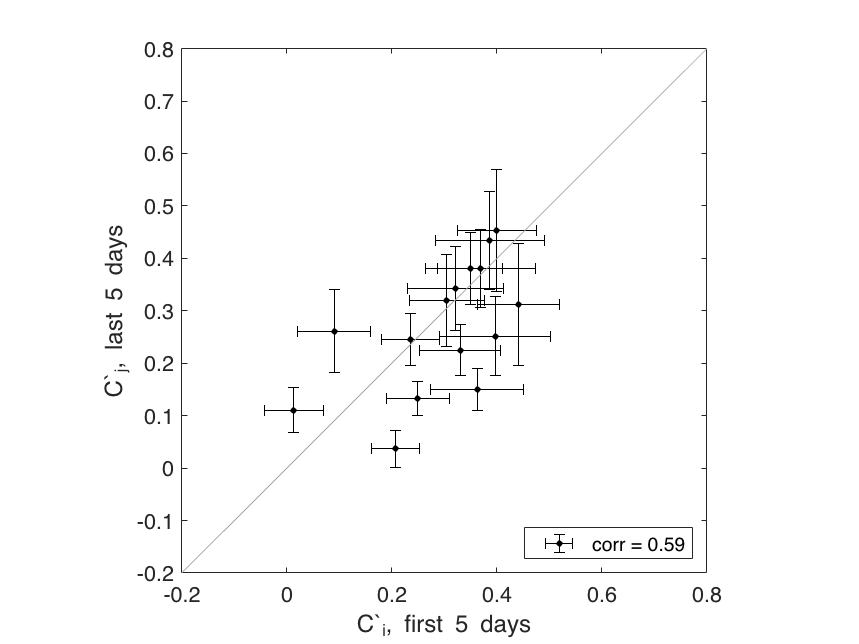

%%
figure()
errorbar(sum(ccijMat_f5), sum(ccijMat_l5),...
    ccijExpSum_l5_bsstd, ccijExpSum_l5_bsstd, ...
    ccijExpSum_f5_bsstd, ccijExpSum_f5_bsstd, ...
    'k.', 'markerSize', 10)
hold on
plot([-1 1],[-1 1],'-','color',[0 0 0]+0.65)
hold off
axis square
axis([-0.2 0.8 -0.2 0.8])
c = corr(sum(ccijMat_f5)', sum(ccijMat_l5)');

l=legend(['corr = ' num2str(c,2)]);
l.Location = 'southeast';
xlabel('C`_{i}, first 5 days')
ylabel('C`_{j}, last 5 days')
set(gca,'fontsize',12)

## Fig. S1. H

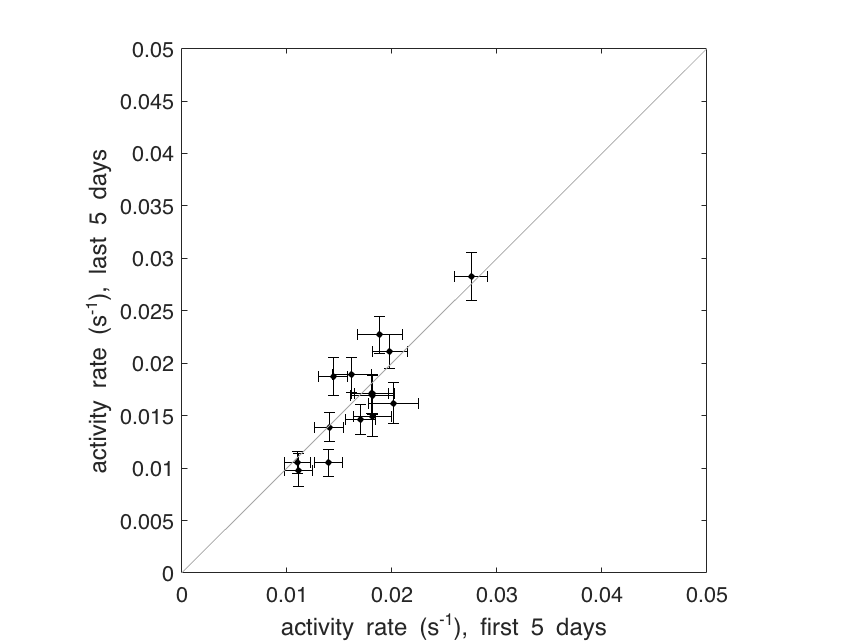

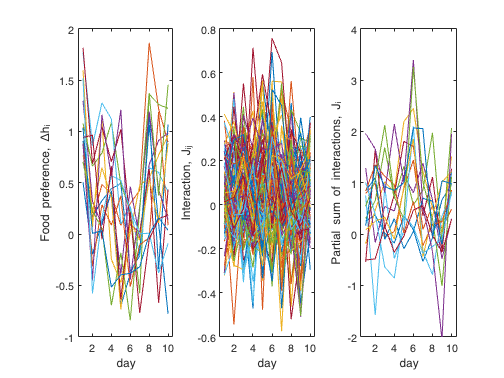

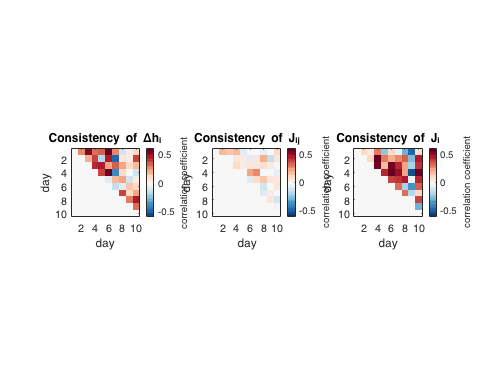

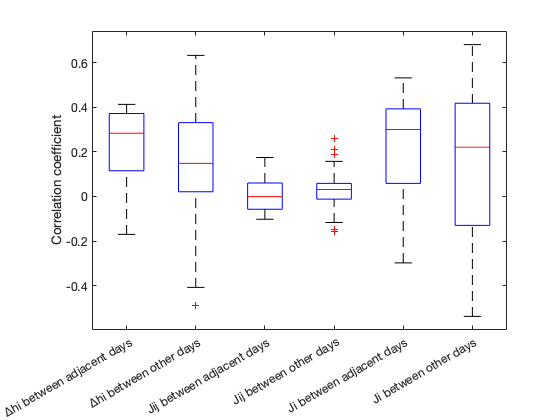

%% Plot rate_activity
% rate of activity = number of activity / time

ractiv_f5 = sum(diff(s2(:,1:10800*5),1,2)~=0,2)/(3600*6*5);
ractiv_l5 = sum(diff(s2(:,(1:10800*5)+10800*5),1,2)~=0,2)/(3600*6*5);

ractiv_f5_bsmaster = zeros(0);
ractiv_l5_bsmaster = zeros(0);

dsSignal = s2(:,1:10800*5);
for ibs = 1:nbs
    bsSignal = bootstrapData(dsSignal',1800)';
    nBsSamples = size(bsSignal,2);
    ractiv_f5_bsmaster(ibs,:) = ...
        sum(diff(bsSignal,1,2)~=0,2)/nBsSamples;
end

dsSignal = s2(:,(1:10800*5)+10800*5);
for ibs = 1:nbs
    bsSignal = bootstrapData(dsSignal',1800)';
    nBsSamples = size(bsSignal,2);
    ractiv_l5_bsmaster(ibs,:) = ...
        sum(diff(bsSignal,1,2)~=0,2)/nBsSamples;
end

ractiv_l5_bsstd = nanstd(ractiv_l5_bsmaster)/sqrt(nSamples/nBsSamples);
ractiv_f5_bsstd = nanstd(ractiv_f5_bsmaster)/sqrt(nSamples/nBsSamples);

%%
figure()
errorbar(ractiv_f5, ractiv_l5, ...
    ractiv_l5_bsstd, ractiv_l5_bsstd, ...
    ractiv_f5_bsstd, ractiv_f5_bsstd, ...
    'k.','MarkerSize',10)
hold on
plot([0 0.05],[0 0.05],'color',[0 0 0]+0.65)
hold off
axis square
axis([0 1 0 1]*0.05)
xlabel('activity rate (s^{-1}), first 5 days')
ylabel('activity rate (s^{-1}), last 5 days')
set(gca,'FontSize', 12)